## **ĐỒ ÁN 1 - NHẬN DẠNG LỆNH THOẠI SỬ DỤNG TƯƠNG QUAN CHÉO**

**Nhóm 6**

1. Huỳnh Tấn Phát - MSSV: 24200144

2. Lưu Hữu Phước - MSSV: 24200150

3. Đặng Văn Trung - MSSV: 24200192

4. Trương Công Vinh - MSSV: 24200204**Môn học: Xử lý tín hiệu số**

5. Phan Thành Nhân - MSSV: 24200140

6. Nguyễn Thanh Tuấn - MSSV: 24200199

7. Vàng Minh Trương - MSSV: 24200193

Live Script thực hiện toàn bộ quy trình trong MATLAB: thu âm, nhận dạng, trực quan hóa, kiểm thử nhiễu và đánh giá phương pháp cải tiến. Chương trình không cần Python và không tạo recordings3.mat.

### **Khởi tạo chương trình**

Xóa biến cũ, đóng các cửa sổ hình và bắt đầu một phiên thực nghiệm mới.

close all;
clearvars;
clc;

### **1. Thiết lập thông số ghi âm**

Thiết lập tần số lấy mẫu 44.100 Hz, độ sâu 16 bit, một kênh và thời lượng 2 giây cho mỗi lệnh.

fs = 44100;             % Tần số lấy mẫu (Hz)
nBits = 16;             % Số bit trên mỗi mẫu
nChannels = 1;          % Ghi âm mono
durationSeconds = 2;    % Thời lượng mỗi mẫu (giây)
noiseEnergyRatio = 0.1; % E_noise = E_signal/10
nTrials = 100;          % Số lần kiểm thử nhiễu

fprintf('THONG SO GHI AM\n');

THONG SO GHI AM


fprintf('Tan so lay mau : %d Hz\n', fs);

Tan so lay mau : 44100 Hz


fprintf('Do sau bit     : %d bit\n', nBits);

Do sau bit     : 16 bit


fprintf('So kenh        : %d (mono)\n', nChannels);

So kenh        : 1 (mono)


fprintf('Thoi luong     : %.1f giay/mau\n', durationSeconds);

Thoi luong     : 2.0 giay/mau


### **2. Thu trực tiếp ba tín hiệu trong MATLAB**

Chương trình chờ người dùng nhấn Enter trước từng lần thu. Ba tín hiệu Open, Close và testSample được giữ trong Workspace, không ghi ra tệp MAT.

% Trước mỗi lần thu, chương trình chờ người dùng nhấn Enter. Sau đó MATLAB
% ghi đúng 2 giây và giữ tín hiệu trong các biến Open, Close và testSample.

input('Chuan bi noi lenh "Open". Nhan Enter de bat dau ghi am: ', 's');
disp('DANG GHI AM LENH "OPEN"...');

DANG GHI AM LENH "OPEN"...


Open = recordSample(fs, nBits, nChannels, durationSeconds);
disp('Da ghi xong lenh "Open".');

Da ghi xong lenh "Open".



input('Chuan bi noi lenh "Close". Nhan Enter de bat dau ghi am: ', 's');
disp('DANG GHI AM LENH "CLOSE"...');

DANG GHI AM LENH "CLOSE"...


Close = recordSample(fs, nBits, nChannels, durationSeconds);
disp('Da ghi xong lenh "Close".');

Da ghi xong lenh "Close".



input(['Chuan bi noi lenh can kiem tra ("Open" hoac "Close"). ' ...
       'Nhan Enter de bat dau ghi am: '], 's');
disp('DANG GHI AM LENH KIEM TRA...');

DANG GHI AM LENH KIEM TRA...


testSample = recordSample(fs, nBits, nChannels, durationSeconds);
disp('Da ghi xong lenh kiem tra.');

Da ghi xong lenh kiem tra.



testLabel = strtrim(input( ...
    'Nhan that cua testSample (Open/Close, Enter neu khong danh nhan): ', 's'));
if ~isempty(testLabel) && ~any(strcmpi(testLabel, {'Open', 'Close'}))
    warning('Nhan khong hop le. Chuong trinh bo qua testLabel.');
    testLabel = '';
end

validateRecordedSignal(Open, 'Open');
validateRecordedSignal(Close, 'Close');
validateRecordedSignal(testSample, 'testSample');

### **3. Trực quan hóa tín hiệu trong miền thời gian**

Ba dạng sóng được vẽ trên cùng thang thời gian để quan sát vị trí và biên độ các vùng phát âm.

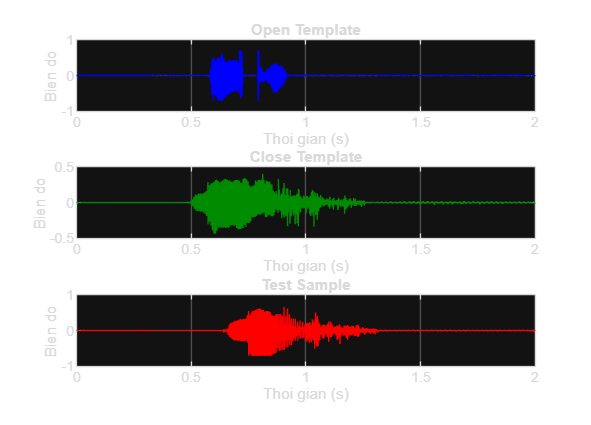

t = (0:numel(Open)-1) / fs;

figure('Name', 'Dang song tin hieu', 'Color', 'w', ...
       'Position', [100, 80, 1000, 720]);

subplot(3, 1, 1);
plot(t, Open, 'b');
grid on;
title('Open Template');
xlabel('Thoi gian (s)');
ylabel('Bien do');

subplot(3, 1, 2);
plot(t, Close, 'Color', [0 0.55 0]);
grid on;
title('Close Template');
xlabel('Thoi gian (s)');
ylabel('Bien do');

subplot(3, 1, 3);
plot(t, testSample, 'r');
grid on;
title('Test Sample');
xlabel('Thoi gian (s)');
ylabel('Bien do');

### **4. Nhận dạng cơ bản bằng tương quan chéo**

Hệ thống lấy đỉnh tương quan chéo giữa testSample với từng mẫu chuẩn. Mẫu có điểm lớn hơn quyết định lệnh dự đoán.

% Điểm của mỗi lệnh là giá trị lớn nhất của tương quan chéo giữa tín hiệu
% cần kiểm tra và mẫu chuẩn. Lệnh có điểm lớn hơn là kết quả dự đoán.

[basicLabel, correlationOpen, correlationClose] = ...
    classifyByXcorr(testSample, Open, Close);

fprintf('\n--- NHAN DANG CO BAN ---\n');


--- NHAN DANG CO BAN ---


fprintf('corr(testSample, Open)  = %.6f\n', correlationOpen);

corr(testSample, Open)  = 52.833638


fprintf('corr(testSample, Close) = %.6f\n', correlationClose);

corr(testSample, Close) = 53.287738


fprintf('Ket qua du doan         = %s\n', basicLabel);

Ket qua du doan         = Close



if ~isempty(testLabel)
    fprintf('Nhan that               = %s -> %s\n', testLabel, ...
        statusText(strcmpi(basicLabel, testLabel)));
else
    fprintf(['Khong co nhan that, vi vay khong tinh do chinh xac cho ' ...
             'testSample.\n']);
end

Nhan that               = Close -> DUNG



if strcmp(basicLabel, 'Open')
    disp('Lenh dieu khien: MO.');
else
    disp('Lenh dieu khien: DONG.');
end

Lenh dieu khien: DONG.


### **5. Tính năng lượng tín hiệu**

Năng lượng rời rạc của mỗi tín hiệu được tính bằng tổng bình phương các mẫu.

% Năng lượng rời rạc được tính theo E = sum(x[n]^2).

EOpen = signalEnergy(Open);
EClose = signalEnergy(Close);
ETest = signalEnergy(testSample);

fprintf('\n--- NANG LUONG TIN HIEU ---\n');


--- NANG LUONG TIN HIEU ---


fprintf('E_Open       = %.6f\n', EOpen);

E_Open       = 481.654991


fprintf('E_Close      = %.6f\n', EClose);

E_Close      = 272.173342


fprintf('E_testSample = %.6f\n', ETest);

E_testSample = 668.694746


### **6. Thêm nhiễu Gaussian có năng lượng bằng 1/10 tín hiệu**

Nhiễu được co giãn để E_noise = E_signal/10, tương ứng SNR 10 dB. Open và Close sau khi thêm nhiễu được phân loại lại để kiểm tra.

% Khi E_noise = E_signal/10 thì:
% SNR = 10*log10(E_signal/E_noise) = 10 dB.

rng(42, 'twister');
[OpenNoisy, noiseOpen] = addGaussianNoiseExact(Open, noiseEnergyRatio);
[CloseNoisy, noiseClose] = addGaussianNoiseExact(Close, noiseEnergyRatio);

ENoiseOpen = signalEnergy(noiseOpen);
ENoiseClose = signalEnergy(noiseClose);
SNROpen = 10 * log10(EOpen / ENoiseOpen);
SNRClose = 10 * log10(EClose / ENoiseClose);

assert(abs(ENoiseOpen/EOpen - noiseEnergyRatio) < 1e-12, ...
    'Nang luong nhieu Open khong bang E_Open/10.');
assert(abs(ENoiseClose/EClose - noiseEnergyRatio) < 1e-12, ...
    'Nang luong nhieu Close khong bang E_Close/10.');

[labelOpenNoisy, corrOO, corrOC] = ...
    classifyByXcorr(OpenNoisy, Open, Close);
[labelCloseNoisy, corrCO, corrCC] = ...
    classifyByXcorr(CloseNoisy, Open, Close);

fprintf('\n--- KIEM TRA NHIEU GAUSSIAN ---\n');


--- KIEM TRA NHIEU GAUSSIAN ---


fprintf('E_noise_Open  = %.6f = E_Open/10, SNR = %.2f dB\n', ...
    ENoiseOpen, SNROpen);

E_noise_Open  = 48.165499 = E_Open/10, SNR = 10.00 dB


fprintf('Open + nhieu  -> %s (Open=%.6f, Close=%.6f): %s\n', ...
    labelOpenNoisy, corrOO, corrOC, ...
    statusText(strcmp(labelOpenNoisy, 'Open')));

Open + nhieu  -> Open (Open=482.018242, Close=108.647407): DUNG



fprintf('E_noise_Close = %.6f = E_Close/10, SNR = %.2f dB\n', ...
    ENoiseClose, SNRClose);

E_noise_Close = 27.217334 = E_Close/10, SNR = 10.00 dB


fprintf('Close + nhieu -> %s (Open=%.6f, Close=%.6f): %s\n', ...
    labelCloseNoisy, corrCO, corrCC, ...
    statusText(strcmp(labelCloseNoisy, 'Close')));

Close + nhieu -> Close (Open=107.988540, Close=272.476860): DUNG


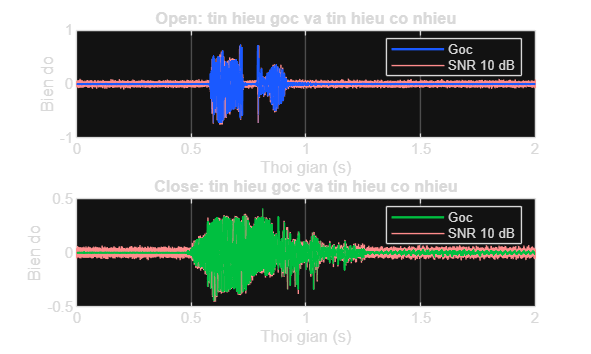


figure('Name', 'Nhieu Gaussian tai SNR 10 dB', 'Color', 'w', ...
       'Position', [120, 100, 1000, 600]);

subplot(2, 1, 1);
hOpenNoisy = plot(t, OpenNoisy, 'Color', [1.0 0.55 0.55], ...
    'LineWidth', 0.45);
hold on;
hOpenClean = plot(t, Open, 'Color', [0.1 0.35 1.0], ...
    'LineWidth', 1.35);
grid on;
title('Open: tin hieu goc va tin hieu co nhieu');
xlabel('Thoi gian (s)');
ylabel('Bien do');
legend([hOpenClean, hOpenNoisy], {'Goc', 'SNR 10 dB'});

subplot(2, 1, 2);
hCloseNoisy = plot(t, CloseNoisy, 'Color', [1.0 0.55 0.55], ...
    'LineWidth', 0.45);
hold on;
hCloseClean = plot(t, Close, 'Color', [0.0 0.75 0.25], ...
    'LineWidth', 1.35);
grid on;
title('Close: tin hieu goc va tin hieu co nhieu');
xlabel('Thoi gian (s)');
ylabel('Bien do');
legend([hCloseClean, hCloseNoisy], {'Goc', 'SNR 10 dB'});

### **7. Giải pháp tăng độ ổn định**

Phương pháp cải tiến loại DC, lọc thông dải 100-4.000 Hz, cắt khoảng lặng và sử dụng tương quan chéo chuẩn hóa.

% Quy trình đề xuất:
% 1. Loại thành phần DC.
% 2. Lọc thông dải 100-4000 Hz.
% 3. Cắt khoảng lặng theo năng lượng khung 20 ms.
% 4. Dùng tương quan chéo chuẩn hóa để giảm ảnh hưởng của âm lượng.

OpenProcessed = preprocessSpeech(Open, fs);
CloseProcessed = preprocessSpeech(Close, fs);
testProcessed = preprocessSpeech(testSample, fs);

[improvedLabel, normalizedOpen, normalizedClose] = ...
    classifyNormalized(testProcessed, OpenProcessed, CloseProcessed);

fprintf('\n--- NHAN DANG SAU TIEN XU LY ---\n');


--- NHAN DANG SAU TIEN XU LY ---


fprintf('NCC(testSample, Open)  = %.6f\n', normalizedOpen);

NCC(testSample, Open)  = 0.098884


fprintf('NCC(testSample, Close) = %.6f\n', normalizedClose);

NCC(testSample, Close) = 0.132814


fprintf('Ket qua sau tien xu ly = %s\n', improvedLabel);

Ket qua sau tien xu ly = Close



if ~isempty(testLabel)
    fprintf('Nhan that               = %s -> %s\n', testLabel, ...
        statusText(strcmpi(improvedLabel, testLabel)));
end

Nhan that               = Close -> DUNG


### **8. Kiểm thử lặp 100 lần tại SNR 10 dB**

Chương trình sinh 100 dãy nhiễu độc lập cho mỗi lệnh và so sánh tỷ lệ nhận đúng giữa phương pháp cơ bản với phương pháp sau tiền xử lý.

% Open và Close có nhãn đã biết nên được dùng để kiểm tra độ ổn định khi
% thêm nhiều dãy nhiễu Gaussian khác nhau. Kết quả này chỉ phản ánh hai bản
% ghi hiện tại, không phải độ chính xác tổng quát trên nhiều người nói.

basicCorrectOpen = 0;
basicCorrectClose = 0;
improvedCorrectOpen = 0;
improvedCorrectClose = 0;

rng(2026, 'twister');
for trial = 1:nTrials
    OpenTrial = addGaussianNoiseExact(Open, noiseEnergyRatio);
    CloseTrial = addGaussianNoiseExact(Close, noiseEnergyRatio);

    basicOpenLabel = classifyByXcorr(OpenTrial, Open, Close);
    basicCloseLabel = classifyByXcorr(CloseTrial, Open, Close);

    improvedOpenLabel = classifyNormalized( ...
        preprocessSpeech(OpenTrial, fs), OpenProcessed, CloseProcessed);
    improvedCloseLabel = classifyNormalized( ...
        preprocessSpeech(CloseTrial, fs), OpenProcessed, CloseProcessed);

    basicCorrectOpen = basicCorrectOpen + strcmp(basicOpenLabel, 'Open');
    basicCorrectClose = basicCorrectClose + strcmp(basicCloseLabel, 'Close');
    improvedCorrectOpen = improvedCorrectOpen + ...
        strcmp(improvedOpenLabel, 'Open');
    improvedCorrectClose = improvedCorrectClose + ...
        strcmp(improvedCloseLabel, 'Close');
end

basicAccuracy = 100 * [basicCorrectOpen, basicCorrectClose] / nTrials;
improvedAccuracy = 100 * ...
    [improvedCorrectOpen, improvedCorrectClose] / nTrials;

fprintf('\n--- KET QUA %d LAN THU TAI SNR 10 dB ---\n', nTrials);


--- KET QUA 100 LAN THU TAI SNR 10 dB ---


fprintf('Co ban - Open : %d/%d (%.1f%%)\n', ...
    basicCorrectOpen, nTrials, basicAccuracy(1));

Co ban - Open : 100/100 (100.0%)


fprintf('Co ban - Close: %d/%d (%.1f%%)\n', ...
    basicCorrectClose, nTrials, basicAccuracy(2));

Co ban - Close: 100/100 (100.0%)


fprintf('Cai tien - Open : %d/%d (%.1f%%)\n', ...
    improvedCorrectOpen, nTrials, improvedAccuracy(1));

Cai tien - Open : 100/100 (100.0%)


fprintf('Cai tien - Close: %d/%d (%.1f%%)\n', ...
    improvedCorrectClose, nTrials, improvedAccuracy(2));

Cai tien - Close: 100/100 (100.0%)


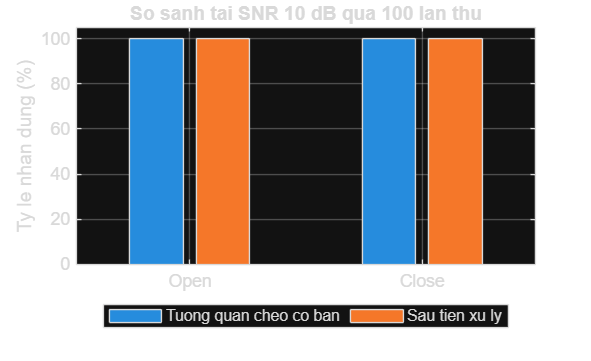


figure('Name', 'So sanh hai phuong phap', 'Color', 'w', ...
       'Position', [160, 120, 850, 520]);
accuracyMatrix = [basicAccuracy(1), improvedAccuracy(1); ...
                  basicAccuracy(2), improvedAccuracy(2)];
bar(accuracyMatrix);
grid on;
ylim([0 105]);
set(gca, 'XTickLabel', {'Open', 'Close'});
ylabel('Ty le nhan dung (%)');
title(sprintf('So sanh tai SNR 10 dB qua %d lan thu', nTrials));
legend('Tuong quan cheo co ban', 'Sau tien xu ly', ...
       'Location', 'southoutside', 'Orientation', 'horizontal');

### **Các hàm cục bộ**

Các hàm bên dưới đóng gói thao tác ghi âm, tính năng lượng, thêm nhiễu, phân loại và tiền xử lý.

function sample = recordSample(fs, nBits, nChannels, durationSeconds)
    recorder = audiorecorder(fs, nBits, nChannels);
    recordblocking(recorder, durationSeconds);
    sample = getaudiodata(recorder, 'double');
    sample = sample(:);
end

function validateRecordedSignal(x, signalName)
    if isempty(x) || any(~isfinite(x))
        error('Tin hieu %s khong hop le.', signalName);
    end
    if signalEnergy(x) <= 1e-10
        error(['Tin hieu %s gan nhu khong co am thanh. ' ...
               'Hay kiem tra microphone va thu lai.'], signalName);
    end
end

function E = signalEnergy(x)
    x = double(x(:));
    E = sum(x.^2);
end

function [noisySignal, noise] = addGaussianNoiseExact(x, energyRatio)
    x = double(x(:));
    sourceEnergy = signalEnergy(x);
    if sourceEnergy <= eps
        error('Khong the them nhieu vao tin hieu co nang luong bang 0.');
    end

    noise = randn(size(x));
    noise = noise * sqrt(energyRatio * sourceEnergy / signalEnergy(noise));
    noisySignal = x + noise;
end

function [label, scoreOpen, scoreClose] = ...
        classifyByXcorr(x, openTemplate, closeTemplate)
    scoreOpen = max(xcorr(double(x(:)), double(openTemplate(:))));
    scoreClose = max(xcorr(double(x(:)), double(closeTemplate(:))));

    if scoreOpen > scoreClose
        label = 'Open';
    else
        label = 'Close';
    end
end

function y = preprocessSpeech(x, fs)
    x = double(x(:));
    x = x - mean(x);

    [b, a] = butter(4, [100 4000] / (fs/2), 'bandpass');
    y = filtfilt(b, a, x);
    y = trimSilenceByEnergy(y, fs, 20, 0.05);
end

function y = trimSilenceByEnergy(x, fs, frameMs, thresholdRatio)
    frameLength = max(1, round(fs * frameMs / 1000));
    frameCount = floor(numel(x) / frameLength);

    if frameCount < 1
        y = x;
        return;
    end

    usableSignal = x(1:frameCount * frameLength);
    frames = reshape(usableSignal, frameLength, frameCount);
    frameEnergy = sum(frames.^2, 1);

    if max(frameEnergy) <= eps
        y = x;
        return;
    end

    activeFrames = find(frameEnergy > thresholdRatio * max(frameEnergy));

    if isempty(activeFrames)
        y = x;
    else
        firstSample = (activeFrames(1)-1) * frameLength + 1;
        lastSample = min(activeFrames(end) * frameLength, numel(x));
        y = x(firstSample:lastSample);
    end
end

function [label, scoreOpen, scoreClose] = ...
        classifyNormalized(x, openTemplate, closeTemplate)
    scoreOpen = normalizedXcorrPeak(x, openTemplate);
    scoreClose = normalizedXcorrPeak(x, closeTemplate);

    if scoreOpen > scoreClose
        label = 'Open';
    else
        label = 'Close';
    end
end

function score = normalizedXcorrPeak(x, y)
    x = double(x(:));
    y = double(y(:));
    denominator = sqrt(signalEnergy(x) * signalEnergy(y));

    if denominator <= eps
        score = 0;
    else
        score = max(xcorr(x, y)) / denominator;
    end
end

function text = statusText(isCorrect)
    if isCorrect
        text = 'DUNG';
    else
        text = 'SAI';
    end
end